# Example 2.1

% Jonghwan Lee, Feb 2021

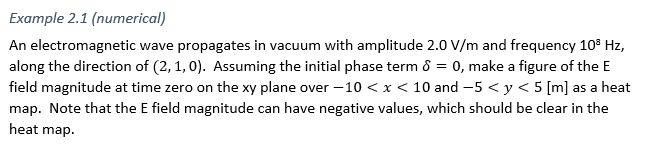

## Constants and given values

clear;

c = 3e8;  % speed of light (m/s)

E0 = 2.0;  % amplitude
nu = 1e8;  % frequency
omega = 2*pi*nu;  % angular frequency
k_hat = [2 1 0] / norm([2 1 0]);  % unit vector of k

k = omega/c*k_hat  % k vector

k =     1.8733    0.9366         0


## Make a 2D array of E field magnitude.

Make a 2D grid of (x,y).

dx = 0.1;  % sampling interval [m]
x = -10:dx:10;
y = -5:dx:5;  % set dy = dx
[gx,gy] = ndgrid(x,y);
size(gx)  % check the size

ans =    201   101


gx

gx =   -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000
   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -

gy

gy =    -5.0000   -4.9000   -4.8000   -4.7000   -4.6000   -4.5000   -4.4000   -4.3000   -4.2000   -4.1000   -4.0000   -3.9000   -3.8000   -3.7000   -3.6000   -3.5000   -3.4000   -3.3000   -3.2000   -3.1000   -3.0000   -2.9000   -2.8000   -2.7000   -2.6000   -2.5000   -2.4000   -2.3000   -2.2000   -2.1000   -2.0000   -1.9000   -1.8000   -1.7000   -1.6000   -1.5000   -1.4000   -1.3000   -1.2000   -1.1000   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000
   -5.0000   -4.9000   -4.8000   -4.7000   -4.6000   -4.5000   -4.4000   -4.3000   -4.2000   -4.1000   -4.0000   -3.9000   -3.8000   -3.7000   -3.6000   -3.5000   -3.4000   -3.3000   -3.2000   -3.1000   -3.0000   -2.9000   -2.8000   -2.7000   -2.6000   -2.5000   -2.4000   -2.3000   -2.2000   -2.1000   -2.0000   -1.9000   -1.8000   -1.7000   -1.6000   -1.5000   -1.4000   -1.3000   -1.2000   -1.1000   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -

Make the 2D array of E field magnitude.

E = E0 * cos(k(1)*gx + k(2)*gy + k(3)*0);  % z = 0 on the xy plane, t = 0

Plot the 2D array as an image.

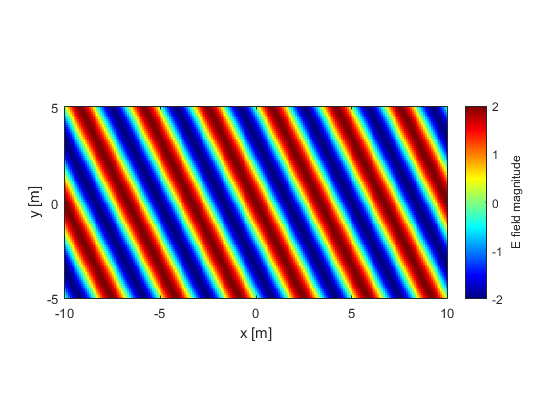

figure;  colormap(jet);  % use the colormap of jet to clearly visualize the negative values in blue
imagesc(x,y,E');  % use the transpose because imagesc() plots the first dimension of the 2D array (x here) in the vertical axis
set(gca,'ydir','normal');  % without this, imagesc() has the vertical axis start from the top
axis image;  % make x and y scale identical
set(gca,'clim',[-2 2]);  % we know the E field magnitude should be between -2 and 2.
cb = colorbar;
cb.Label.String = 'E field magnitude';
% cb.Label.Rotation = 270;  cb.Label.Position(1) = 3;
xlabel('x [m]');
ylabel('y [m]');